## Tutorial 4: Two step optimization part one: the cell finding module

In this tutorial, we will discuss the first important step of optimizing EXTRACT's hyperparameters: the cell finding module. For this tutorial, we use a two-photon calcium imaging movie collected following the published guidelines, which is courtesy of Ben Yang -Parker Lab. See Parker, J.G., Marshall, J.D., Ahanonu, B. et al. Diametric neural ensemble dynamics in parkinsonian and dyskinetic states. Nature 557, 177–182 (2018). https://doi.org/10.1038/s41586-018-0090-6 Extended Data Fig 4 for more information on the imaging and experimental conditions.

setupEXTRACT; % add EXTRACT to the path if it is not already there

### Watching the preprocessed movie

As the first step, we watch the preprocessed movie and ensure that the motion is properly corrected and the spatial filtering does not introduce significant artifacts.

jones_file = getEXTRACTsampleData('jones.h5');

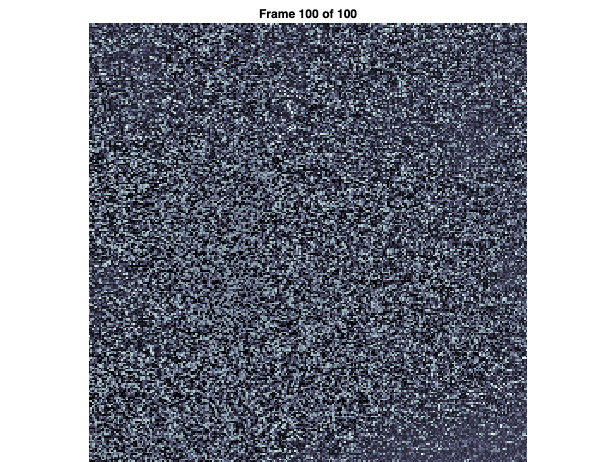


M = h5read(jones_file,'/data');
config = get_defaults([]);
M_proc = preprocess_movie(M,config);
view_movie(M_proc(:,:,1:100))

From watching the preprocessed movie, it is rather clear that we are aiming to perform cell extraction from a rather low SNR movie, in which the cells are barely visible to the eye. Thus, cell finding module likely needs to be tweaked to account for this fact.

### Cell extraction with defaults

We start with a simple cell extraction using mainly the default parameters.

M = [jones_file ':/data'];
config = get_defaults([]);
config.downsample_time_by = 4;
config.use_gpu = 0;
output = extractor(M,config);

25-Jul-2024 16:20:04: Signal extraction will run on 1 partitions serially... 
25-Jul-2024 16:20:04: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.1743 
	 	 	 	 minimum magnitude: 0.2400 
	 	 	 46 cells found after a total of 69 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 24 (22 removed) 
	 	 	 End of iter # 2: # cells: 24 (0 removed) 
	 	 	 End of iter # 3: # cells: 24 (0 removed) 
	 	 	 End of iter # 4: # cells: 24 (0 removed) 
	 	 	 End of iter # 5: # cells: 24 (0 removed) 
	 	 	 End of iter # 6: # cells: 24 (0 removed) 
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 24 cells.
25-Jul-2024 16:21:04: Total of 24 cells are found.
25-Jul-2024 16:21:04: Removing duplicate cells...
25-Jul-2024 16:21:04: 24 cells were retained after removing duplicates.
25-Jul-2024 16

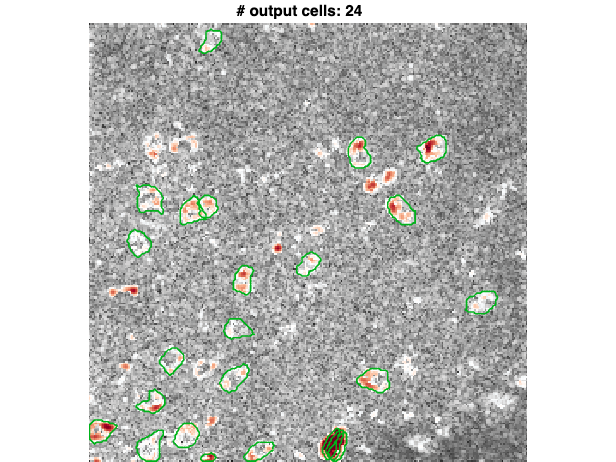

plot_output_cellmap(output,[],[],'clim_scale',[0, 0.999])

drawnow

As expected, the cell extraction with default values missed several cells. There may be several reasons, one of which is the failure of the cell finding module. To test this, we can turn off the cell refinement process and watch the cell extraction real-time as it is happening with following the code:

25-Jul-2024 16:21:06: Signal extraction will run on 1 partitions serially... 
25-Jul-2024 16:21:06: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.1743 
	 	 	 	 minimum magnitude: 0.2400 


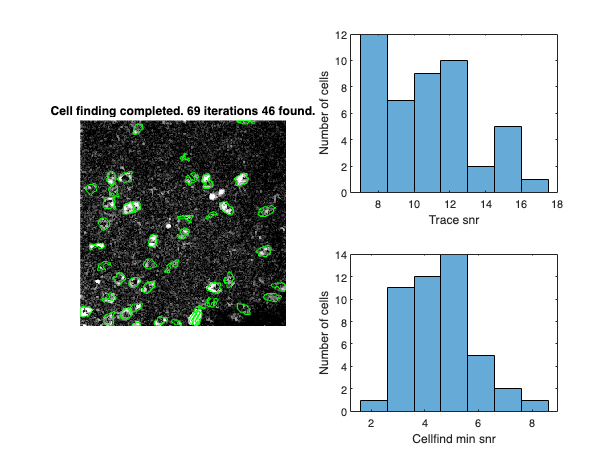

	 	 	 46 cells found after a total of 69 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 46 cells.
25-Jul-2024 16:22:14: Total of 46 cells are found.
25-Jul-2024 16:22:14: Removing duplicate cells...
25-Jul-2024 16:22:14: 46 cells were retained after removing duplicates.
25-Jul-2024 16:22:14: All done with EXTRACT! 


config.max_iter = 0;
config.visualize_cellfinding = 1;
output = extractor(M,config);

Indeed, as can be seen above, cell finding module is missing several low SNR cells that should have been identified.

### Optimizing the cell finding module

To optimize the cell finding module, we will first note that the earlier run had shown an early cutoff for the trace snr values, indicating that more cells might have been found in lower SNR values. Second, the cellfind min snr value was centered around 5 (often should be ~10-100s), a rather low value. Thus, we first pick very low values for both parameters. 

Next, since our main concern is being able to identify cells, we can also decrease the cutoff value for the spatial lowpass filter. This will allow more smoothing of the movie used for the cell finding purposes only.

25-Jul-2024 16:22:15: Signal extraction will run on 1 partitions serially... 
25-Jul-2024 16:22:15: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.0869 
	 	 	 	 minimum magnitude: 0.0328 
			 Step #100, found 87 cells... 


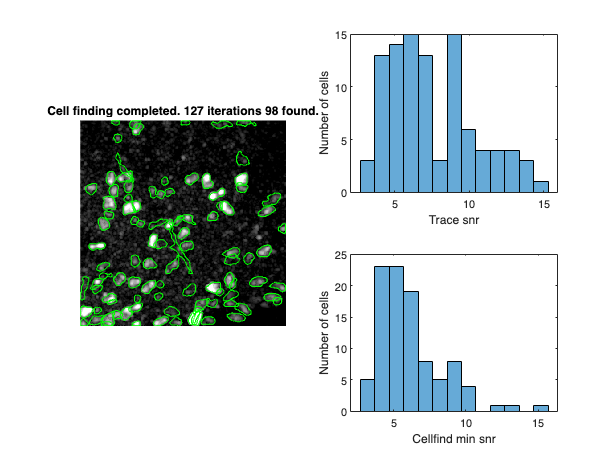

	 	 	 98 cells found after a total of 127 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 98 cells.
25-Jul-2024 16:24:26: Total of 98 cells are found.
25-Jul-2024 16:24:26: Removing duplicate cells...
25-Jul-2024 16:24:26: 98 cells were retained after removing duplicates.
25-Jul-2024 16:24:26: All done with EXTRACT! 


M = [jones_file ':/data'];
config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.max_iter = 0;
config.visualize_cellfinding = 1;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.5;
output = extractor(M,config);

And voila! We have achieved a satisfactory cell finding process, where almost all cells (but also some garbage) are found. The next tutorial will discuss how to optimize the cell refinement module, which primarily aims to cull away the false-positive candidates.